## SNR Definition used in 5G Toolbox Link Examples

The SNR definition used in the 5G Toolbox is the average SNR per resource element and per receive antenna. This definition assumes that the average received signal power per resource element (RE) per antenna is $\frac{1}{N_{\textrm{Rx}} }$, where $N_{\textrm{Rx}}$ is the number of receive antennas. Therefore, to achieve a certain SNR, the 5G Toolbox examples set the noise power as:


$$N_0 =\frac{1}{\sqrt{2N_{\textrm{Rx}} N_{\textrm{FFT}} {\textrm{SNR}}_{\textrm{Lin}} }}$$


Where:

- $N_{\textrm{Rx}}$ is the number of receive antennas. This is required because the SNR is measured per receive antenna.

- $N_{\textrm{FFT}}$ is the number of FFT points used in the OFDM modulator, which applies a gain of $\frac{1}{N_{\textrm{FFT}} }$. In the processing chain simulated, the gain applied by the OFDM modulator only affects the signal component and not the noise. Therefore, we need to apply a factor of $\frac{1}{\sqrt{N_{\textrm{FFT}} }}$ to the noise power.

                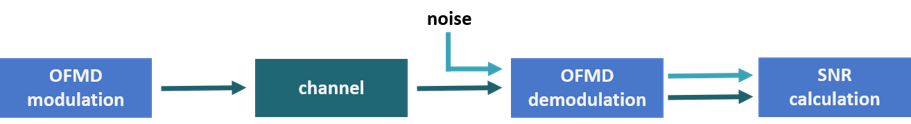

-  ${\textrm{SNR}}_{\textrm{Lin}}$is the SNR in linear scale.

- The factor of 2 accounts for the complex nature of the noise.

- This definition assumes that the average power of the symbols in the resource grid in the transmitter is one. If a scaling factor is applied to these symbols, the noise power equation above must be adjusted by the same amount.

## SNR Verification

The following setup is used to measure the SNR per RE per antenna:

- Generate resource grid with QPSK symbols.

- OFDM modulate the grid.

- Send the resulting signal through the channel.

- Generate AWGN.

- OFDM demodulate the received signal and the noise separately.

- Measure the power of the signal and the noise per RE per antenna.

- Calculate and display the SNR.

Specify the desired SNR in dBs.

SNRdB = 0;
rng('default') % set default random number generator for repeatability

Set the number of transmit and receive antennas.

nTxAnts = 2;
nRxAnts = 4;

Set the number of iterations, this is used to calculate the mean signal and noise power over many channel realizations.

noIterations = 120; % Number of iterations to 

Specify the carrier parameters

carrier = nrCarrierConfig;
carrier.NSizeGrid = 10;          % grid size in resource blocks
carrier.SubcarrierSpacing = 15;  % subcarrier spacing

Specify the channel parameters. The channel type can be TDL or CDL. Several channel parameters can affect the signal power as it propagates through it. The set of parameters used here by default do not change the power of the signal in the mean:

- Set `NormalizePathGains` to `true`: the total power of the path gains averaged over time is 0 dB

- Set `NormalizeChannelOutputs` to `true` to normalize the channel outputs by the number of receive antennas

- In multiantenna scenarios with precoding, use precoding a precoding vector with norm = 1

For the CDL channel model:

- Use isotropic antennas (transmit and receive)

- Align transmit and receive polarization angles so there is no signal loss

- Avoid antenna correlation by providing enough separation between antenna elements

For the TDL channel model:

- For the TDL channel model set `MIMOCorrelation` to `'Low'`

Additionally, the average power of the symbols in the transmit resource grid must be one.

% Channel
ChannelType = 'TDL'; % 'CDL'
dopplerShift = 40;

if strcmpi(ChannelType,'CDL')
    channel = nrCDLChannel; % CDL channel object
    channel.DelayProfile = 'CDL-C';    
    channel.MaximumDopplerShift = dopplerShift;
    channel.NormalizeChannelOutputs = true;
    channel.NormalizePathGains = true; % normalize to make sure all path gains = 0dB
    % Turn the overall number of antennas into a specific antenna panel
    % array geometry
    [channel.TransmitAntennaArray.Size, channel.ReceiveAntennaArray.Size] = ...
        hArrayGeometry(nTxAnts,nRxAnts);
    channel.TransmitAntennaArray.Element = 'isotropic'; % avoid antenna element gains
    channel.ReceiveAntennaArray.Element =  'isotropic'; % avoid antenna element gains
    channel.TransmitAntennaArray.PolarizationAngles = [90 0]; % avoid antenna element gains
    channel.ReceiveAntennaArray.PolarizationAngles = [90 0]; % avoid antenna element gains
    channel.TransmitAntennaArray.ElementSpacing = [10 10 15 15];
    channel.ReceiveAntennaArray.ElementSpacing = [10 10 15 15];
elseif strcmpi(ChannelType,'TDL')
    channel = nrTDLChannel; % TDL channel object
    channel.DelayProfile = 'TDL-A';
    channel.MaximumDopplerShift = dopplerShift;    
    channel.NormalizeChannelOutputs = true;
    channel.NormalizePathGains = true; % normalize to make sure all path gains = 0dB
    channel.NumTransmitAntennas = nTxAnts;
    channel.NumReceiveAntennas = nRxAnts;
    channel.MIMOCorrelation = 'Low';
else
    error("ChannelType ("+string(ChannelType)+") must be either CDL or TDL.");
end


Calculate the signal and channel sampling rate.

% Waveform and channel info
waveformInfo = nrOFDMInfo(carrier);
channel.SampleRate = waveformInfo.SampleRate;
chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + chInfo.ChannelFilterDelay;

Create an empty resource grid and a norm-one precoding vector.

grid = nrResourceGrid(carrier,nTxAnts);
w  = (1/sqrt(nTxAnts))*ones(1,nTxAnts);

Calculate the number of bits and PDSCH symbols to generate. Preallocate signal and noise power buffers.

nSymbols = numel(grid(:,:,1));
modulation = "16QAM";
M = bitsPerSymbol(modulation);
nBits = M*nSymbols; % number of bits

% Signal and noise power values buffers
powSBuffer = zeros(noIterations,nRxAnts);
powNBuffer = zeros(noIterations,nRxAnts);

Calculate noise power from SNR.

% Noise parms
SNR = 10^(SNRdB/20);    % Calculate linear noise gain
N0 = 1/(sqrt(2.0*nRxAnts*double(waveformInfo.Nfft))*SNR);

Measure the received signal and noise powers per RE and receive antenna. Average results over `noIterations` channel realizations.

for k = 1:noIterations    
    % Set new channel seed
    channel.release();
    channel.Seed = randi([1 12345678],1,1);
    
    % Generate symbols, precode and populate grid
    dataBits = randi([0 1],nBits,1);    
    pdschSymb = nrSymbolModulate(dataBits,modulation);
    grid(:) = pdschSymb * w;    
    
    % OFDM Modulate
    txWaveform = nrOFDMModulate(carrier, grid);
        
    % Pad signal with zeros, this guarantees the channel filter is flushed
    % and a full slot gets to te receiver
    txWaveform = [txWaveform; zeros(maxChDelay, size(txWaveform,2))];
    
    % Send signal through channel
    [rxWaveform,pathGains] = channel(txWaveform);
    
    % Generate noise waveform 
    rxNoise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
    
    % Perfect synchronization.    
    pathFilters = getPathFilters(channel); % get path filters for perfect channel estimation
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    rxWaveform = rxWaveform(1+offset:end, :);
    rxNoise = rxNoise(1+offset:end, :);
    
    % OFDM demodulation (signal)
    rxSignalGrid = nrOFDMDemodulate(carrier, rxWaveform);       
    
    % OFDM demodulation (noise)
    rxNoiseGrid = nrOFDMDemodulate(carrier, rxNoise);
    
    % Measure received signal and noise power from the grid, this is the
    % mean power per RE
    for n=1:nRxAnts
        rxSignalGridPerAnt = rxSignalGrid(:,:,n);        
        rxNoiseGridPerAnt = rxNoiseGrid(:,:,n);
        powSBuffer(k,n) = rms(rxSignalGridPerAnt(:)).^2;    
        powNBuffer(k,n) = rms(rxNoiseGridPerAnt(:)).^2;
    end
end

% Calculate and display SNR for each receiver antenna
signalPower = zeros(nRxAnts,1);
noisePower = zeros(nRxAnts,1);
for n=1:nRxAnts
    signalPower(n) = mean(powSBuffer(:,n)); % mean of power for all iterations
    noisePower(n) = mean(powNBuffer(:,n));  % mean of power for all iterations
    disp("Signal power ant. " + string(n) + " = " + string(pow2db(signalPower(n))) + " dB");
    disp("Noise power  ant. " + string(n) + " = " + string(pow2db(noisePower(n))) + " dB");
    disp("SNR ant. " + string(n) + " = " + string(pow2db(signalPower(n)/noisePower(n))) + " dB -------");
end

Signal power ant. 1 = -6.0663 dB


Noise power  ant. 1 = -6.0297 dB


SNR ant. 1 = -0.036662 dB -------


Signal power ant. 2 = -6.1084 dB


Noise power  ant. 2 = -6.0115 dB


SNR ant. 2 = -0.096827 dB -------


Signal power ant. 3 = -5.9595 dB


Noise power  ant. 3 = -6.0303 dB


SNR ant. 3 = 0.07078 dB -------


Signal power ant. 4 = -6.0379 dB


Noise power  ant. 4 = -6.0369 dB


SNR ant. 4 = -0.00098085 dB -------


The measured SNR values should approximate the specified SNR parameter

## Local Functions

function M = bitsPerSymbol(modulation)
switch modulation
    case 'QPSK'
        M = 2;
    case '16QAM'
        M = 4;
    case '64QAM'
        M = 6;
    case '256QAM'
        M = 8;
    otherwise
        error("Modulation "+modulation+" must be onw of ""QPSK"", ""16QAM"", ""64QAM"", ""256QAM"" ")
end
end